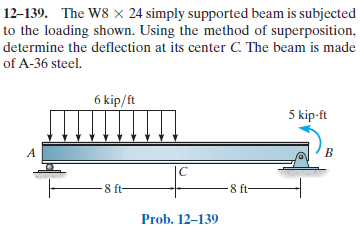

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-139RP-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-139RP-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 16*u.ft);
b = b.add('concentrated', 'moment', 5*u.kip*u.ft, 16*u.ft);
b = b.add('distributed', 'force', -6*u.kip/u.ft, [0 8]*u.ft);
b.L = 16*u.ft;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{x\,\left(24\,x^{3}-581\,x^{2}\,\mathrm{ft}+56576\,{\mathrm{ft}}^{3}\right)}{96\,\text{E}\,\text{I}}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 8\,\mathrm{ft}\\ -\frac{\left(x-16\,\mathrm{ft}\right)\,\left(187\,x^{2}-6224\,x\,\mathrm{ft}+6144\,{\mathrm{ft}}^{2}\right)}{96\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }8\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{96\,x^{3}-1743\,x^{2}\,\mathrm{ft}+56576\,{\mathrm{ft}}^{3}}{96\,\text{E}\,\text{I}}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 8\,\mathrm{ft}\\ -\frac{561\,x^{2}-18432\,x\,\mathrm{ft}+105728\,{\mathrm{ft}}^{2}}{96\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }8\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{x\,\left(48\,x-581\,\mathrm{ft}\right)}{16}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 8\,\mathrm{ft}\\ -\frac{187\,x-3072\,\mathrm{ft}}{16}\,\mathrm{kip} & \text{ if }8\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -\frac{96\,x-581\,\mathrm{ft}}{16}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 8\,\mathrm{ft}\\ -\frac{187}{16}\,\mathrm{kip} & \text{ if }8\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -6\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 8\,\mathrm{ft}\\ 0 & \text{ if }8\,\mathrm{ft}<x \end{array}\right.$$

# reactions and hinges

ra_vpa = vpa(ra) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & 36.3125\,\mathrm{kip}\\ \mathrm{Rb} & 11.6875\,\mathrm{kip} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

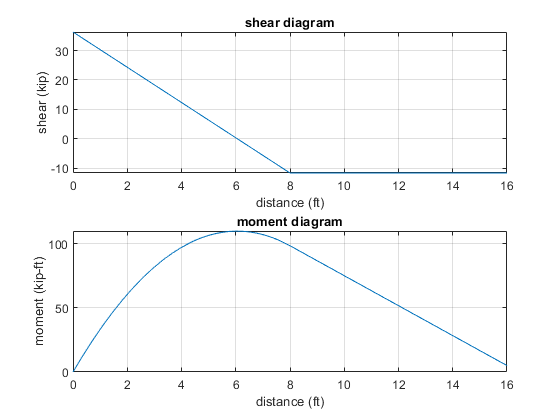

beam.shear_moment(m, v, [0 b.L], {'kip' 'ft'});

# clean up

addvar(y);
setassum(old_assum, 'clear');
clear old_assum;
clear ra_vpa;